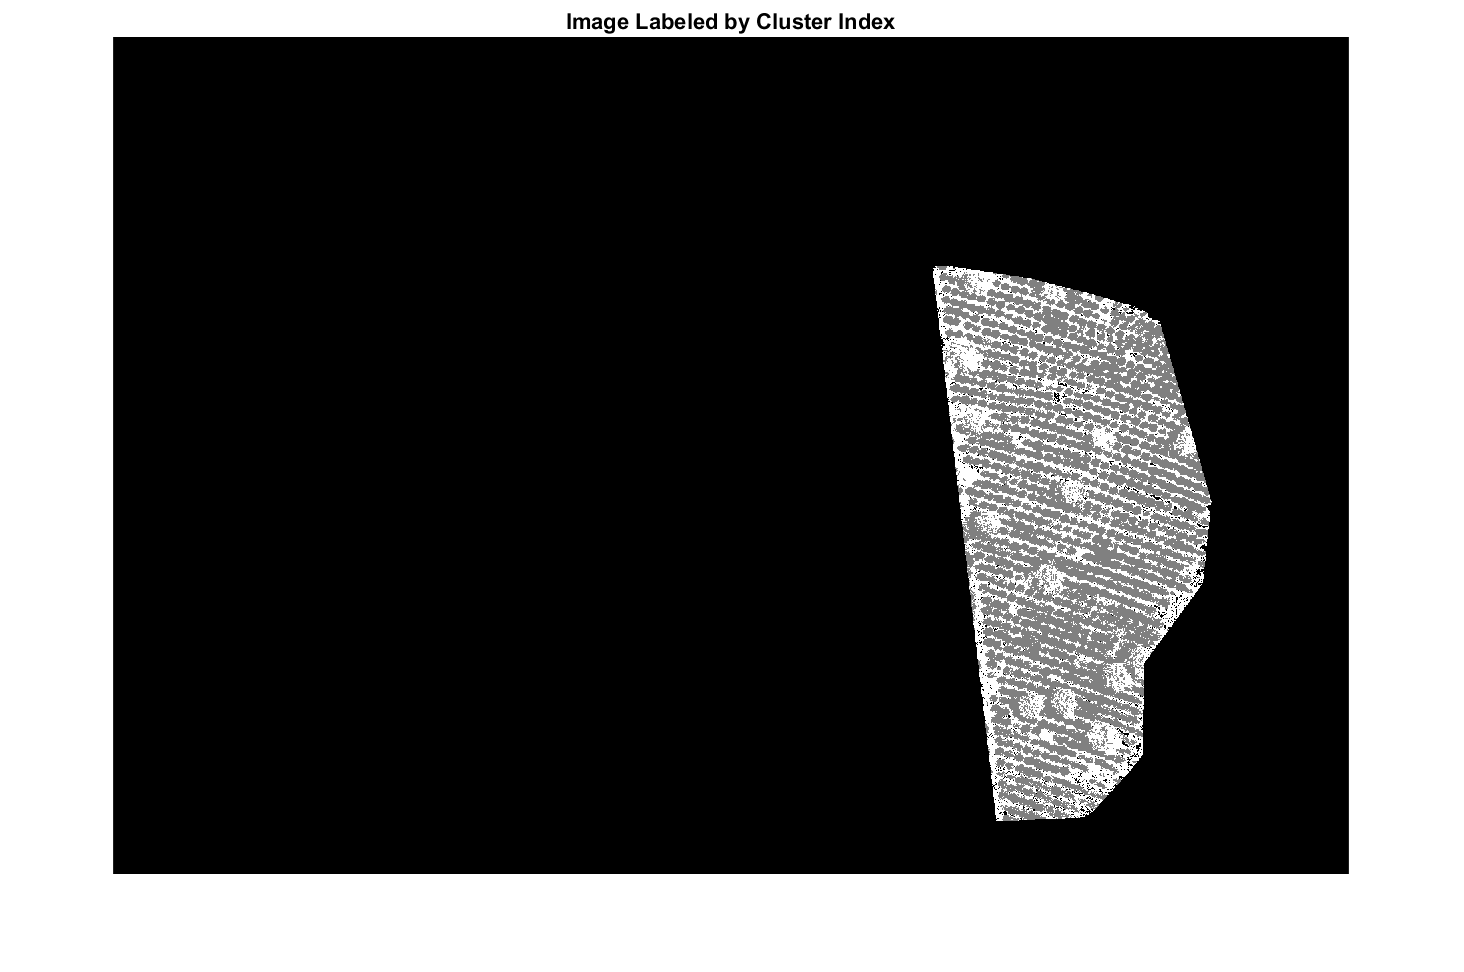

clc;
clear all;
I = imread('odm_orthophoto_3.tif');
Itf = geotiffinfo ('odm_orthophoto_3.tif'); 
[x,y]=pixcenters(Itf);
Band1=I(:,:,1);
Band2=I(:,:,2);
Band3=I(:,:,3);

[m,n,z]=size(I);
imagenRGB7Anios = uint8(zeros(m,n,3));
imagenRGB7Anios(:,:,1)=Band1;
imagenRGB7Anios(:,:,2)=Band2;
imagenRGB7Anios(:,:,3)=Band3;
Band1=imagenRGB7Anios(:,:,1);
mask7=segmentedImage1(imagenRGB7Anios);
imagenRGB7Anios = imagenRGB7Anios.*uint8(mask7);

lab_he = rgb2lab(imagenRGB7Anios);
ab = lab_he(:,:,2:3);
ab = im2single(ab);
nColors = 3;
% repeat the clustering 3 times to avoid local minima
pixel_labels = imsegkmeans(ab,nColors,'NumAttempts',3);
imshow(pixel_labels,[]);
title('Image Labeled by Cluster Index');

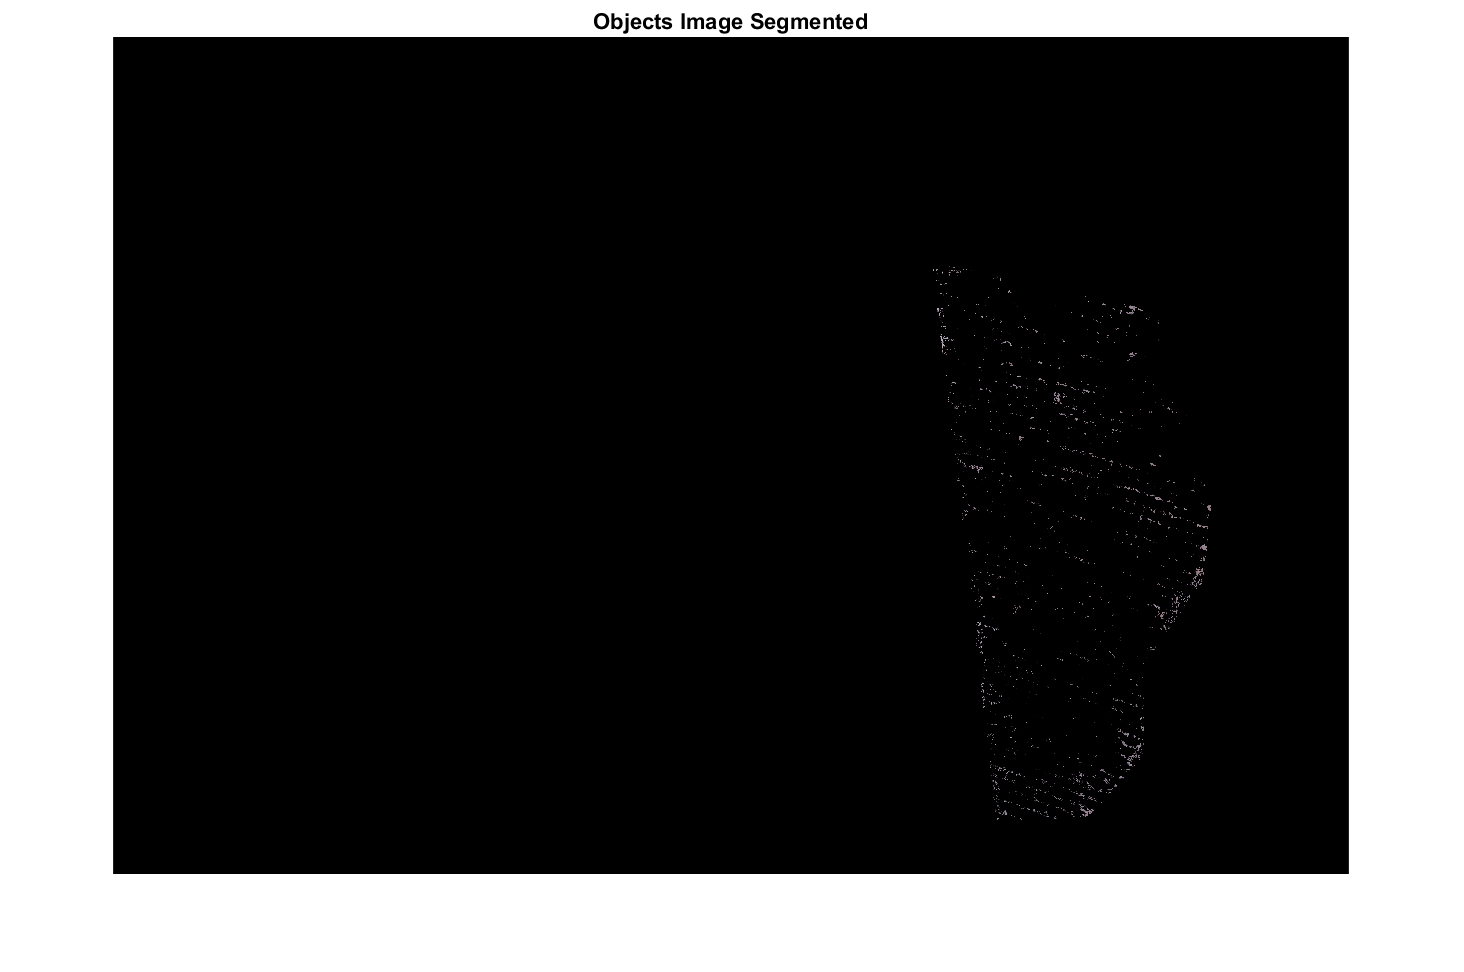

mask1 = pixel_labels==1;
imageSegmented = imagenRGB7Anios .* uint8(mask1);
imshow(imageSegmented)
title('Objects Image Segmented');

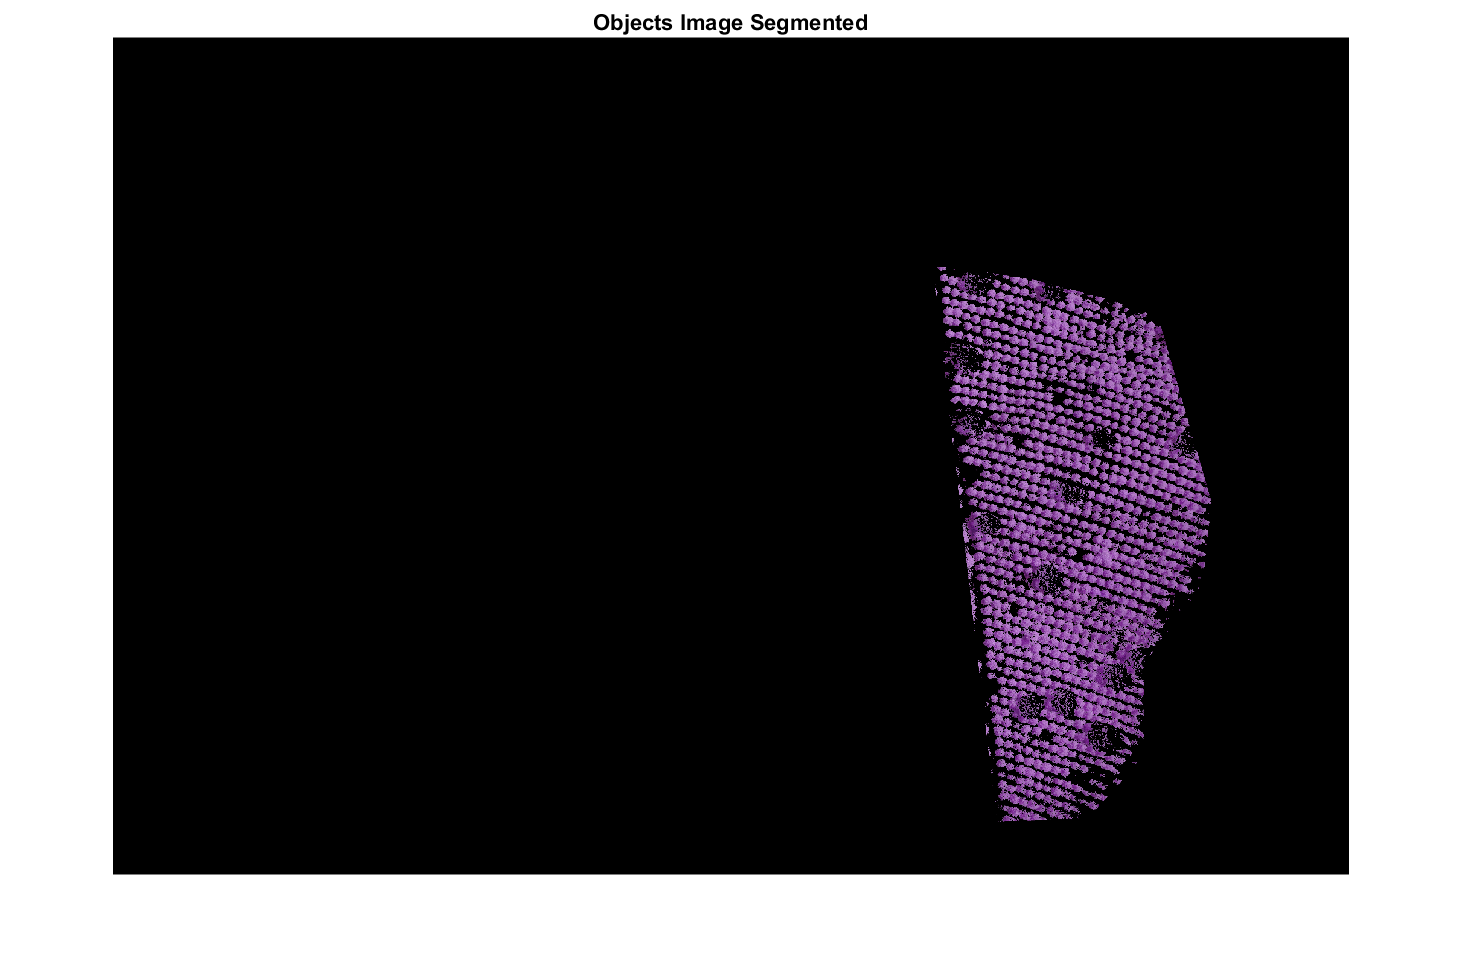

mask1 = pixel_labels==2;
imageSegmented = imagenRGB7Anios .* uint8(mask1);
imshow(imageSegmented)
title('Objects Image Segmented');

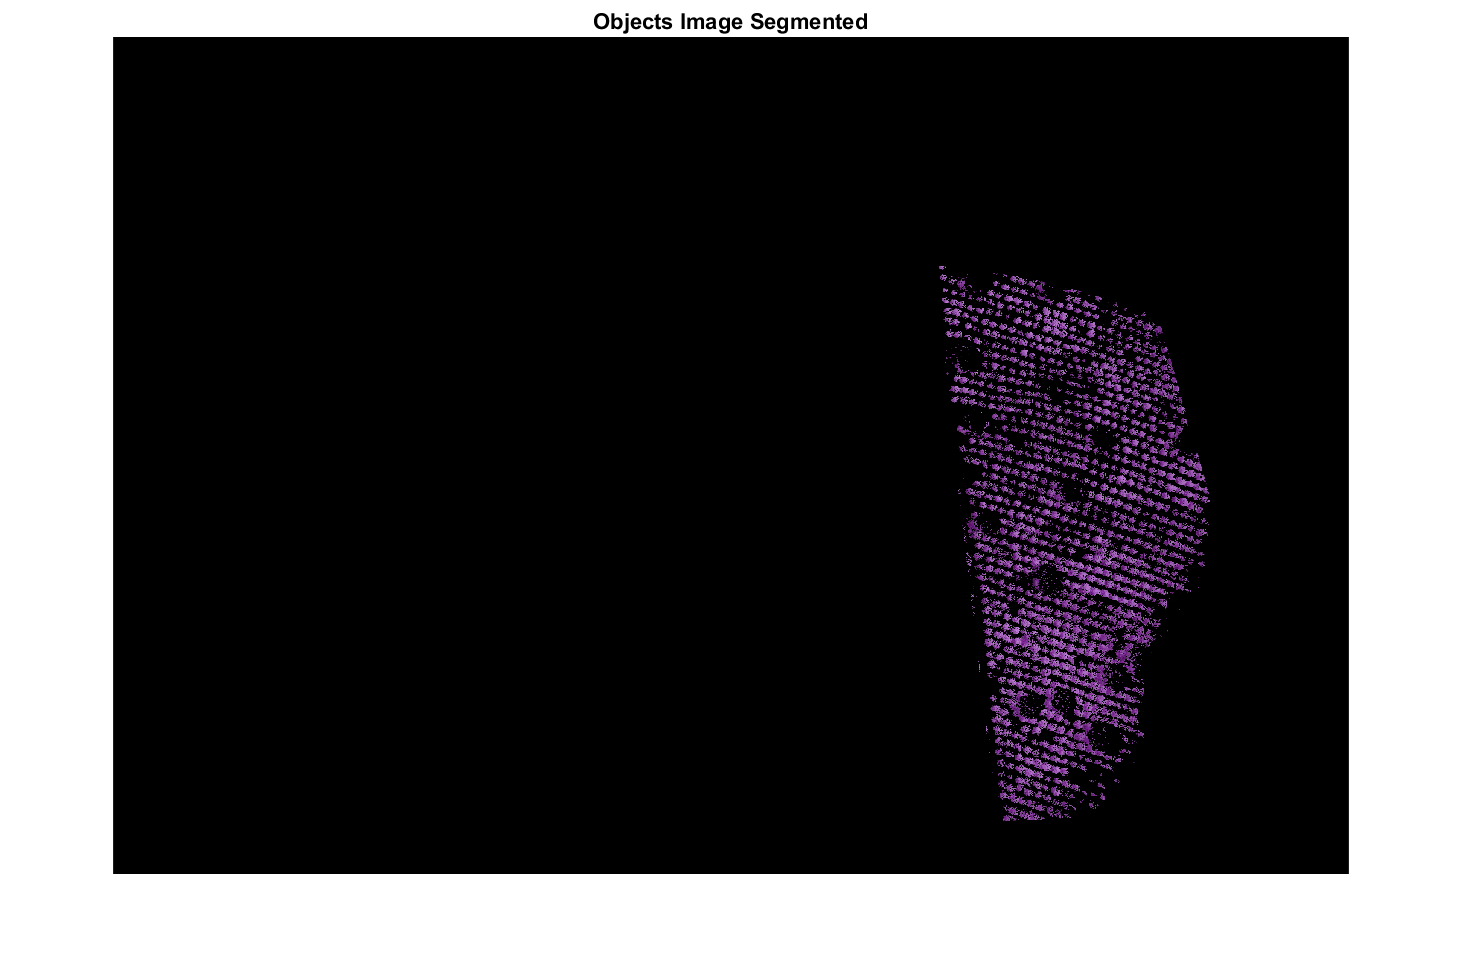

mask1 = pixel_labels==3;
imageSegmented = imagenRGB7Anios .* uint8(mask1);
imshow(imageSegmented)
title('Objects Image Segmented');

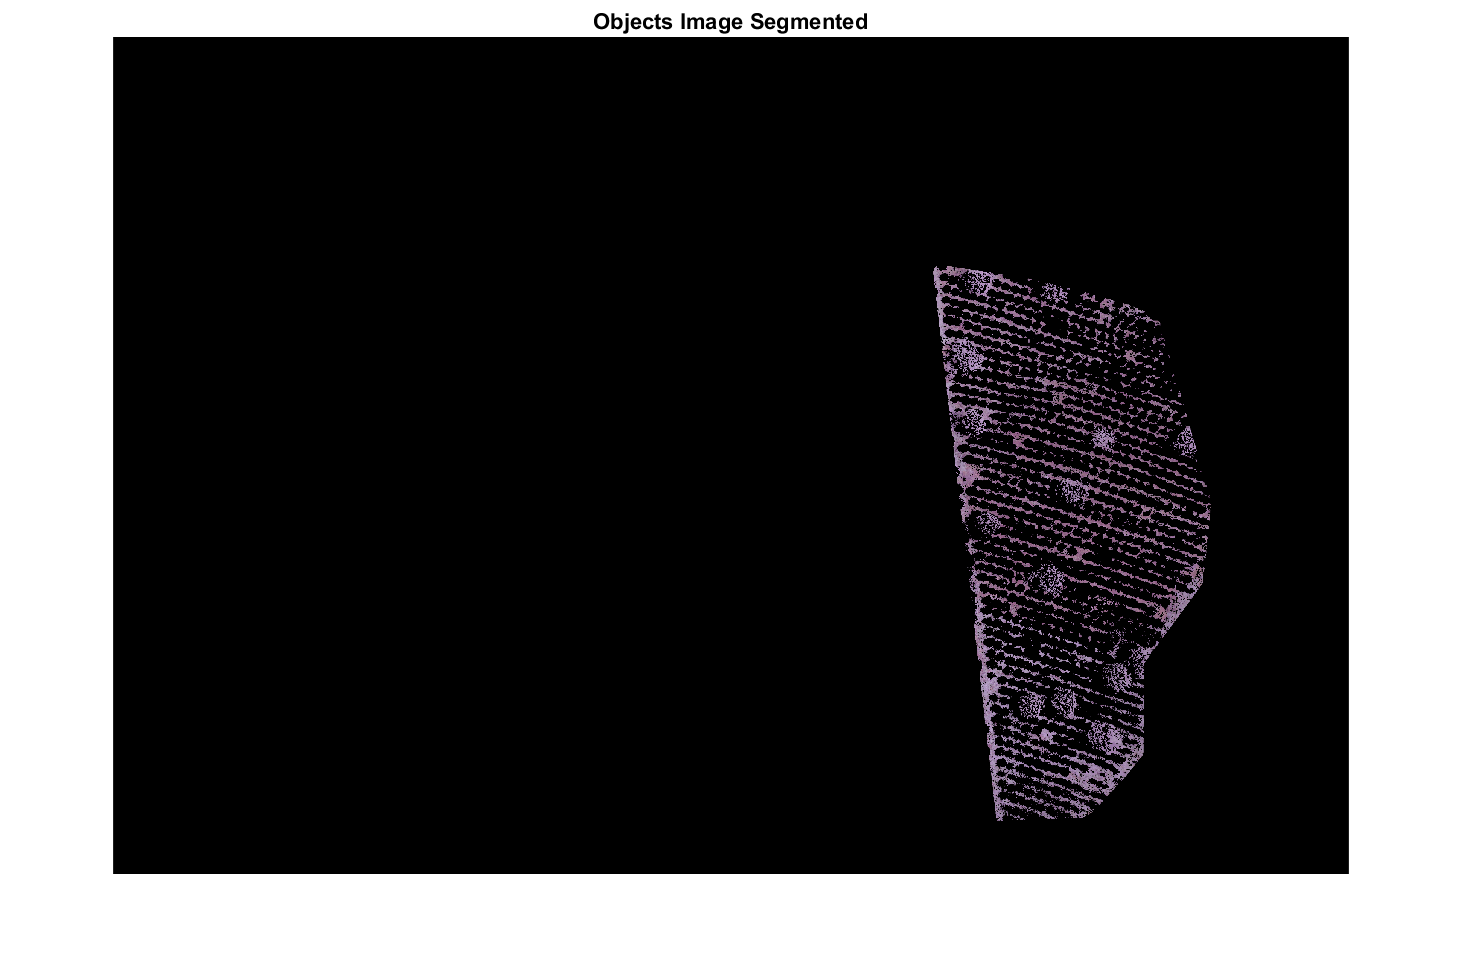

mask1 = pixel_labels==4;
imageSegmented = imagenRGB7Anios .* uint8(mask1);
imshow(imageSegmented)
title('Objects Image Segmented');

Se realiza operación morfológica close. 

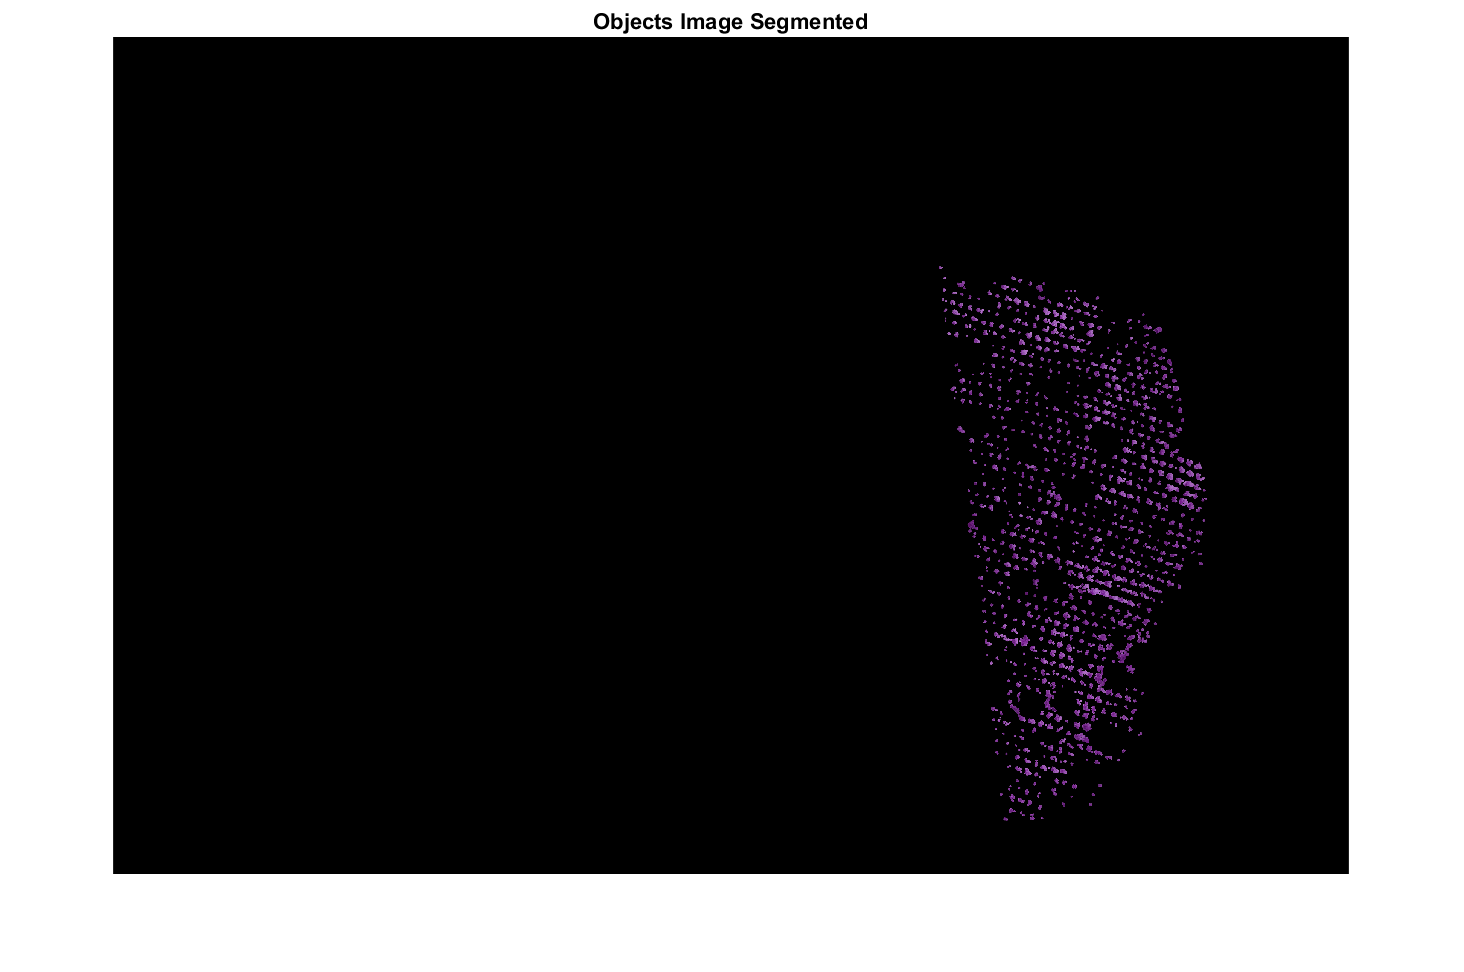

[maskClosed,imageMaskedClosed]= openOperationMorph(imageSegmented,mask1);
imshow(imageMaskedClosed)
title('Objects Image Segmented');

Se realiza operación morfológica close. 

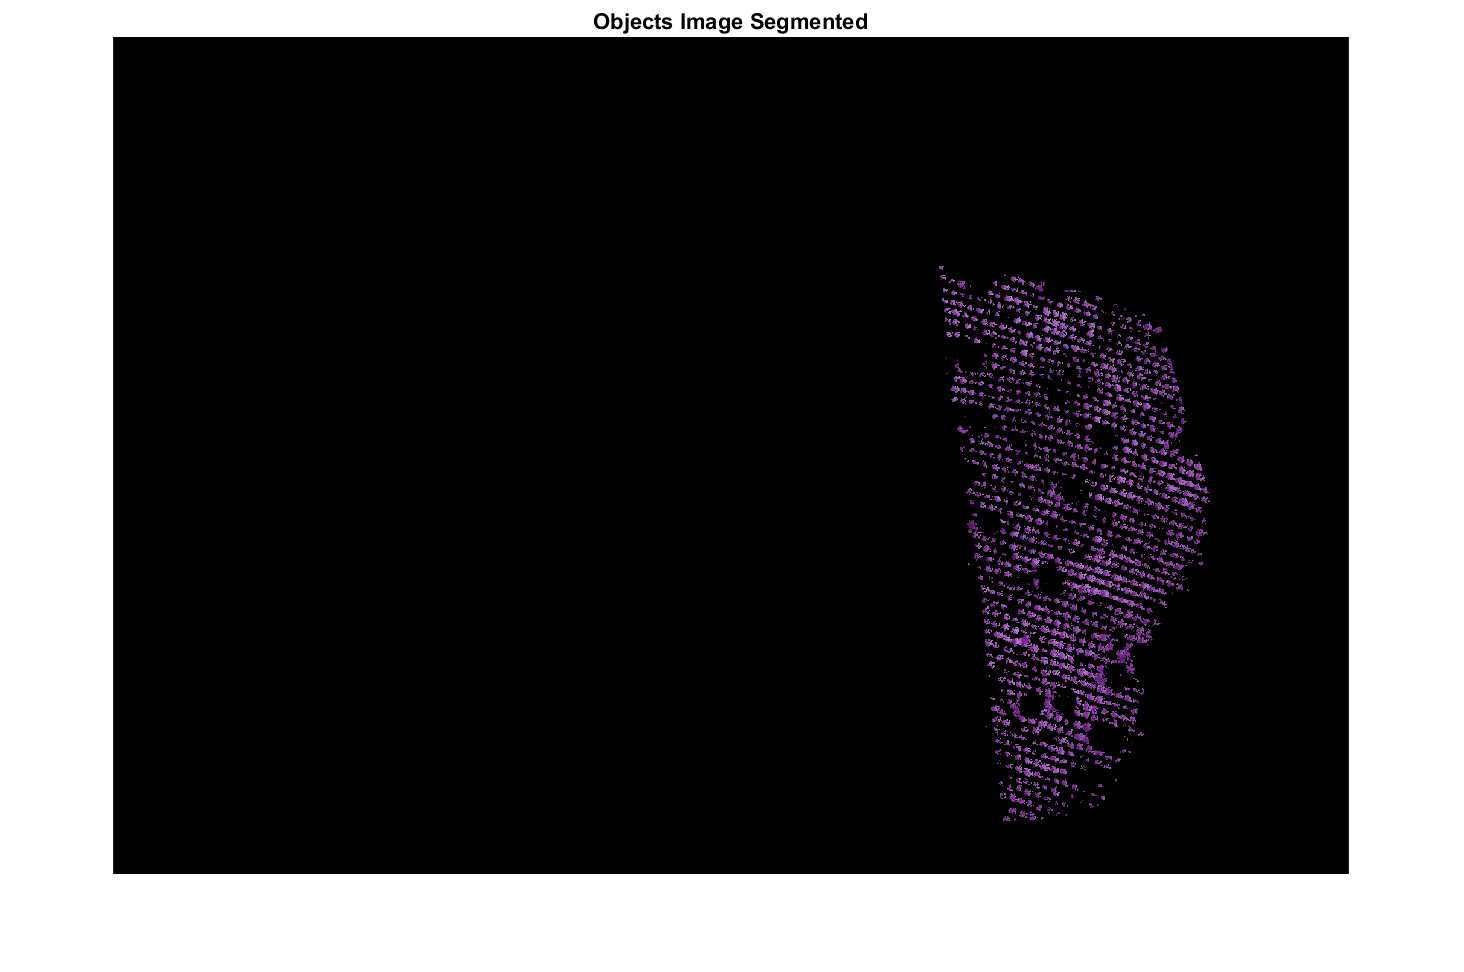

[maskClosed,imageMaskedClosed]= operationMorphClose(imageSegmented,mask1);
imshow(imageMaskedClosed)
title('Objects Image Segmented');

Se realiza Operación ERODE R 3

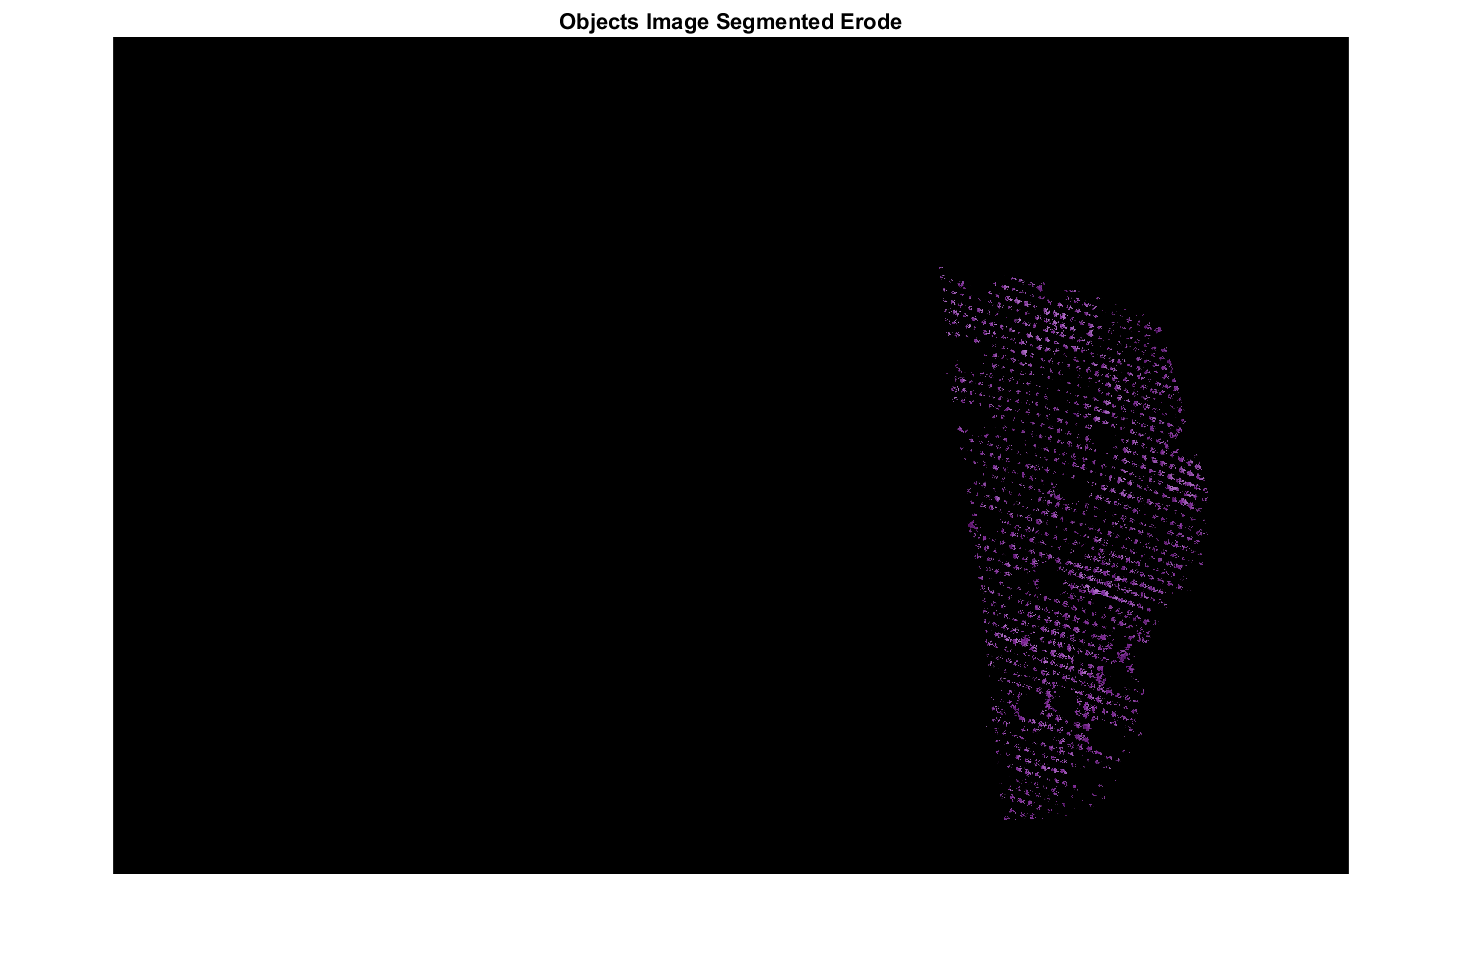

[maskClosed,imageMaskedErode]= erodeOperationMorph(imageSegmented,mask1);
imshow(imageMaskedErode)
title('Objects Image Segmented Erode');

Se realiza OpenCloseOperation

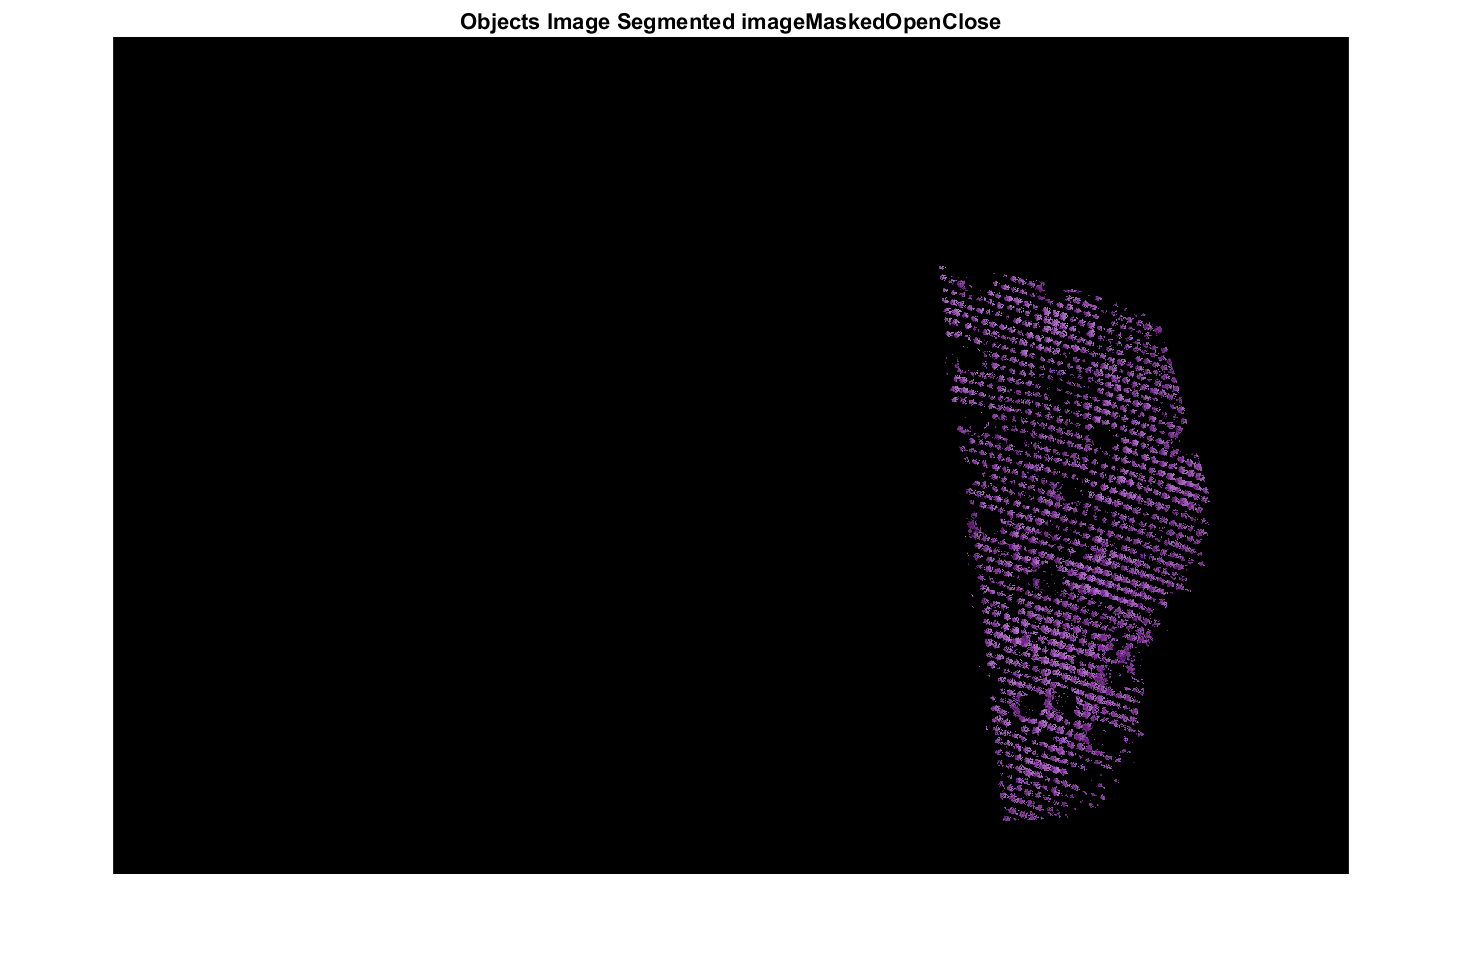

[maskClosed,imageMaskedOpenClose]= mutualOpenCloseMethod(imageSegmented,mask1);
imshow(imageMaskedOpenClose)
title('Objects Image Segmented imageMaskedOpenClose');

## Segmentar de Nuevo

lab_he2 = rgb2lab(imageMaskedClosed);

Unrecognized function or variable 'imageMaskedClosed'.

ab2 = lab_he2(:,:,2:3);
ab2 = im2single(ab2);
% repeat the clustering 3 times to avoid local minima
pixel_labels2 = imsegkmeans(ab2,nColors,'NumAttempts',3);
imshow(pixel_labels2,[]);
title('Image Labeled by Cluster Index');

mask12 = pixel_labels2==3;
imageSegmented = imageMaskedClosed .* uint8(mask12);
imshow(imageSegmented)
title('Objects Image Segmented');

FIND CIRCLES IMAGE SEGMENTED

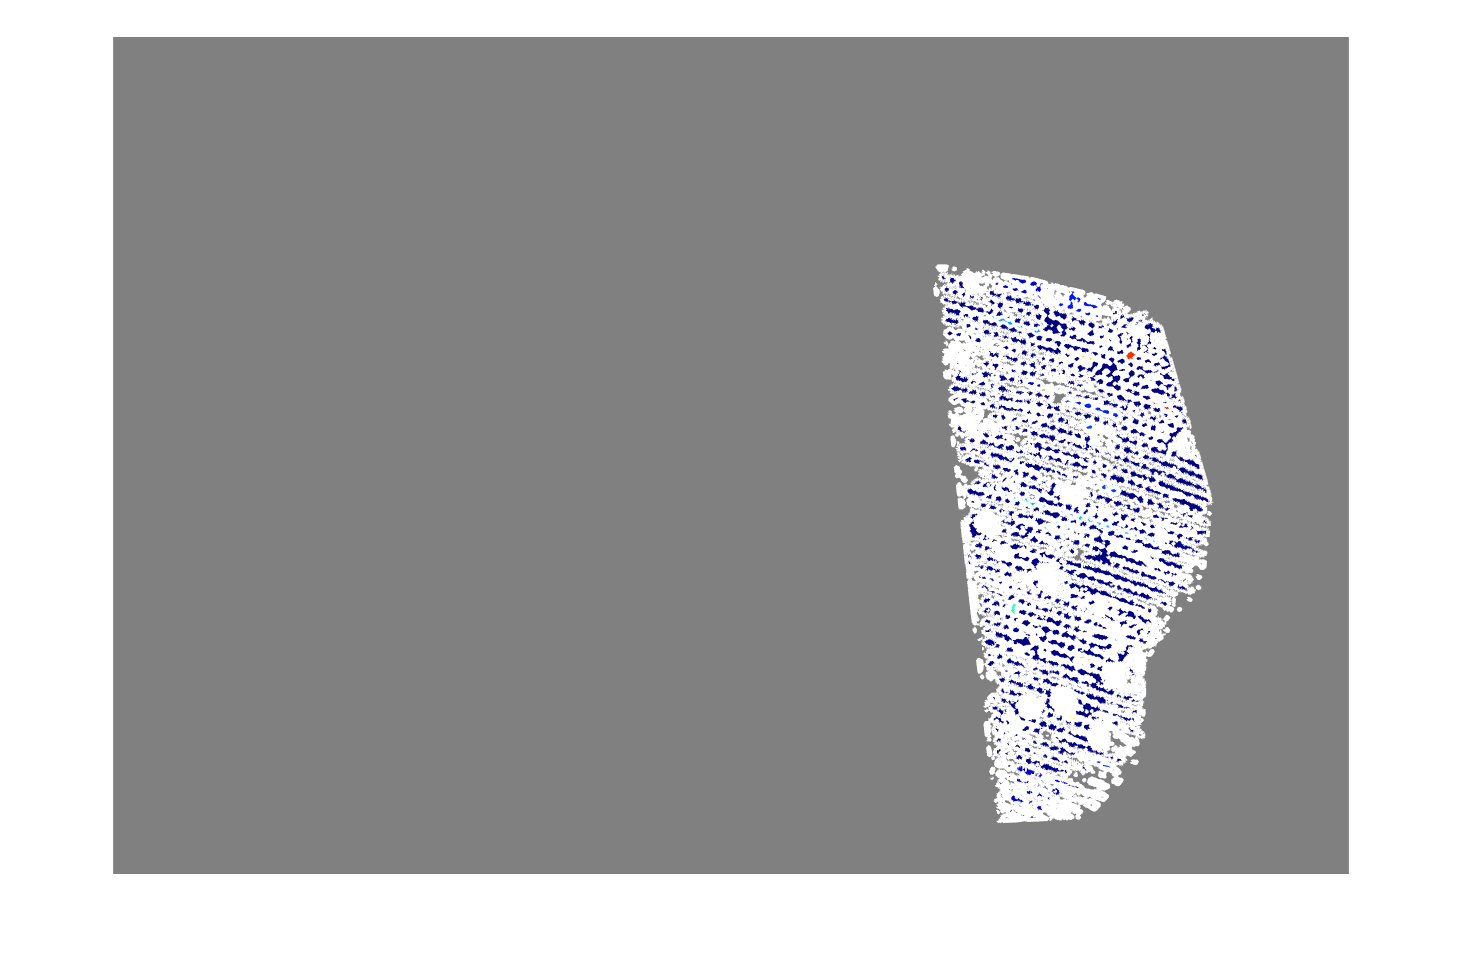


[centers,radii] = imfindcircles(imageSegmented,[22 35],'ObjectPolarity','bright', ...
    'Sensitivity',0.98);
imshow(imageSegmented)

h = viscircles(centers,radii);

[B,L] = bwboundaries(mask1,'holes');
imshow(label2rgb(L, @jet, [.5 .5 .5]))
hold on
for k = 1:length(B)
   boundary = B{k};
   plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 2)
end


[centers,radii] = imfindcircles(imageMaskedErode,[22 36],'ObjectPolarity','bright', ...
    'Sensitivity',0.978)

centers = 	1.0e+03 *

    6.1085    2.0194
    5.5518    1.6787
    6.0108    2.2721
    5.9492    2.6996
    6.1845    2.5765
    5.0573    2.1097
    5.4210    2.7922
    5.4246    1.6957
    5.5003    1.7909
    6.4067    2.6621


radii =    24.7253
   24.0786
   24.8279
   24.6133
   24.9685
   23.9923
   25.7601
   26.4662
   24.6560
   23.4048


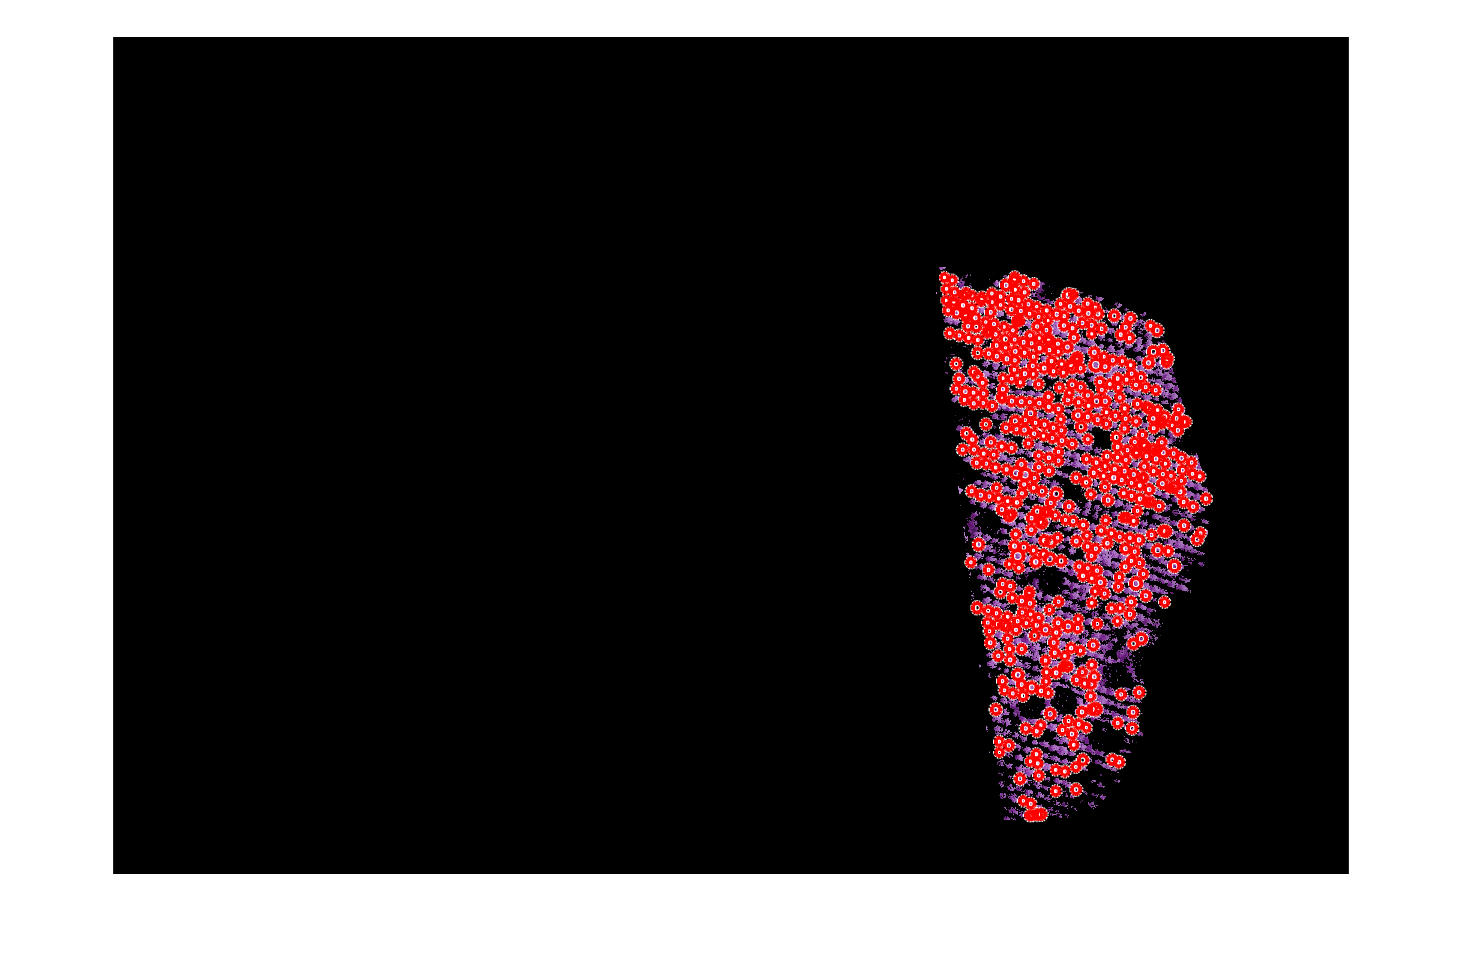

imshow(imageMaskedErode)

h = viscircles(centers,radii);

[centers,radii] = imfindcircles(imageMaskedOpenClose,[22 39],'ObjectPolarity','bright', ...
    'Sensitivity',0.978)

centers = 	1.0e+03 *

    4.9952    1.5772
    5.1545    1.6247
    5.4964    1.6621
    5.4995    1.7882
    5.2724    1.5361
    5.9562    2.8992
    5.1310    1.7321
    5.3870    4.5057
    6.1829    2.5757
    6.1303    2.4317


radii =    24.6655
   24.6682
   26.6384
   25.2889
   24.0128
   24.7816
   24.6216
   23.7546
   27.1693
   26.3203


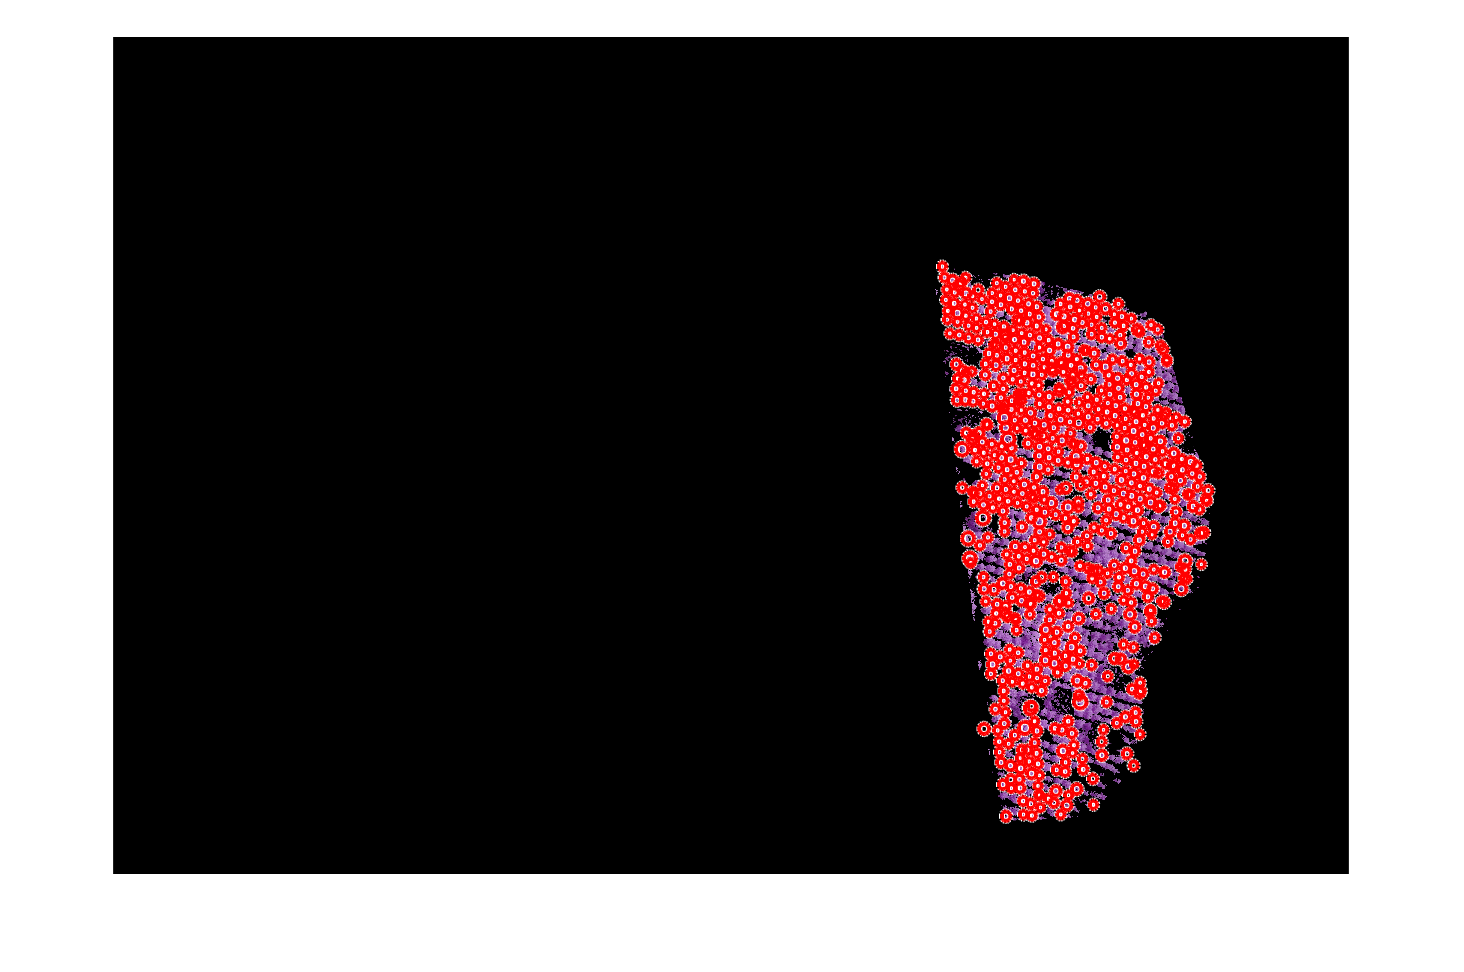

imshow(imageMaskedOpenClose)

h = viscircles(centers,radii);